t_max = 300;
fs = 10000;
t = 0:1/fs:t_max-1/fs;

pyrolysis_temperature = 500;
biomass_temp = 20;
% Using 20kg/h we have:
mass_per_hour = 20;
mass_per_second = mass_per_hour/3.6;% grams per second
vaporisation_rate = 2;% seconds
batches_per_second = 10;
% Then we consider in 100ms batches going into the reactor - 
mass_per_batch = mass_per_second / (batches_per_second);
% Then consider vaporisation rate:
% Hence we have:
mass = mass_per_batch * vaporisation_rate * batches_per_second; % g
% Average Energy/Temperature drop by weight:
temp_after_batch_added = (pyrolysis_temperature * (mass-mass_per_batch)/mass) + ...
                            (biomass_temp * (mass_per_batch/mass));
temp_drop_per_batch = pyrolysis_temperature - temp_after_batch_added;

% Assuming an increase rate
temp_drop_per_second = temp_drop_per_batch*batches_per_second;

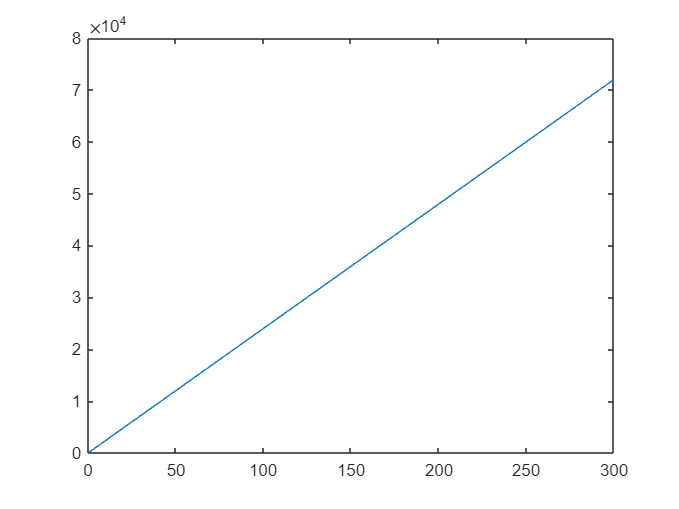

Signal = 240 .* t;
plot(t, Signal)

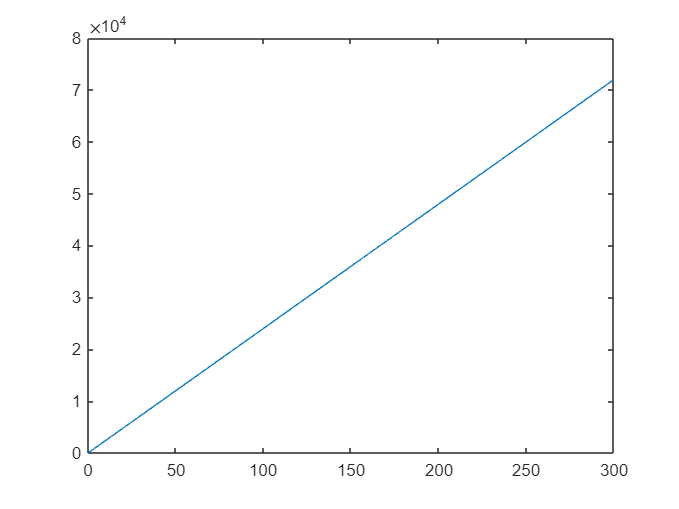

Decreasing_Function = temp_drop_per_second .* floor(100*t)/100 .* ones(size(t));
plot(t, Decreasing_Function)
xlim([0, t_max]);

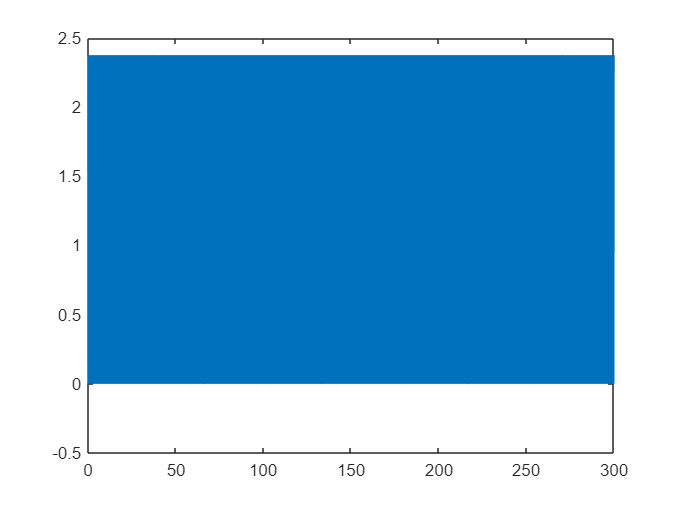

x = (Signal-Decreasing_Function);
N = length(x);                   	% signal length
plot(t, x)

### fftShift

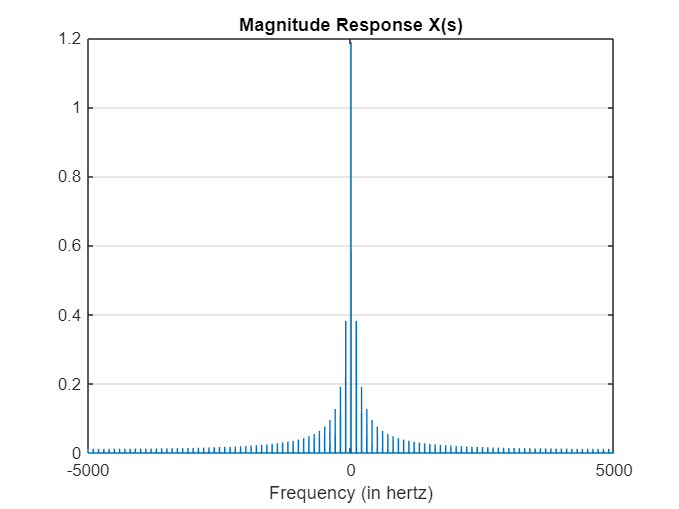

X = fftshift(fft(x));
%% Frequency specifications:
dF = fs/N;                      % hertz
f = -fs/2:dF:fs/2-dF;           % hertz
%%Plot the spectrum:
figure;
plot(f,abs(X)/N);
grid on
xlabel('Frequency (in hertz)');
title('Magnitude Response X(s)');

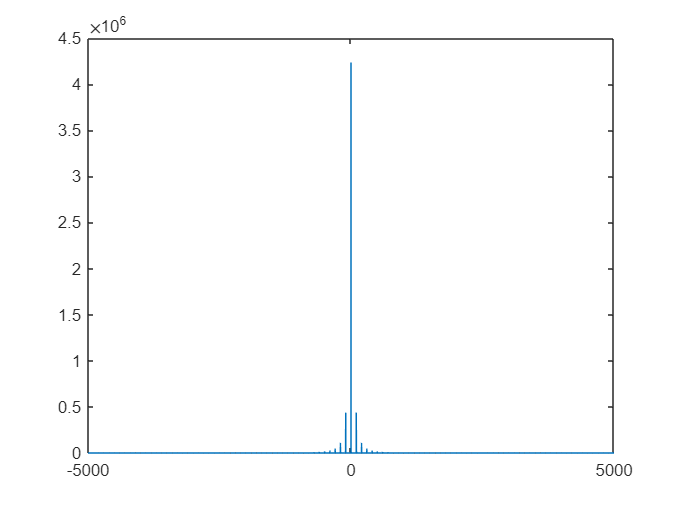

pow = abs(X).^2/N;
plot(f, pow)

## Signal Power Measurement

pRMS = rms(x)^2

pRMS = 1.8913

powbp = bandpower(x,fs,[0 fs/2])

powbp = 1.8912

Verifies that the bandpower is defined correctly in terms of the RMS power

powerPercent = 98

powerPercent = 98

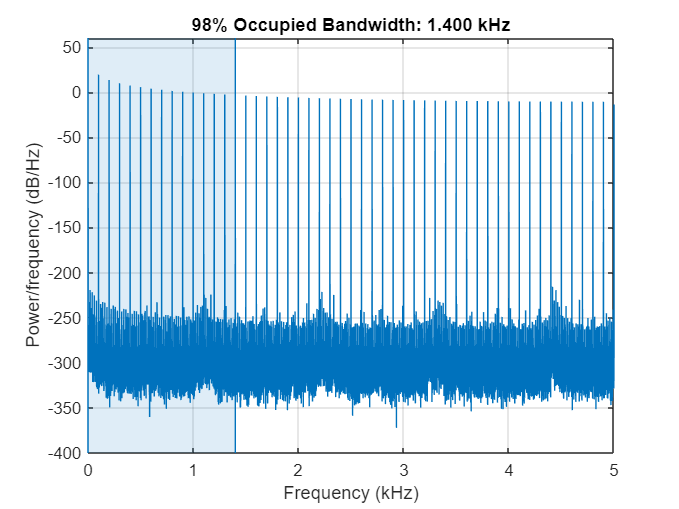

ans = 1.4000e+03

figure
obw(x, fs, [], powerPercent)

pow99 = obw(x,fs, [], powerPercent);